clear;

% Load dataset
datasetName = "dataset15";
files = metadata.selectPreset(metadata.collect('DataSet/Faulty bearing'), datasetName);

pipeline_opt = struct();

%pipeline_opt.exclude = features.registry('currents_w_park');
pipeline_opt.windowOverlap = 0;
% pipeline_opt.exclude = ["Mean_A", ...
%                         "Mean_B", ...
%                         "Std_A", ...
%                         "Std_B", ...
%                         "DominantFreq_A", ...
%                         "DominantFreq_B", ...
%                         "DominantFreq_P", ...
%                         "RMS_A", ... // corr with RMS_Vector_Mag
%                         "RMS_B", ... // corr with RMS_Vector_Mag
%                         "RMS_VectorMag", ... // corr with RMS_P
%                         "SpecEnergy_A", ... // corr with RMS_P
%                         "SpecEnergy_B", ... // corr with RMS_P
%                         "SpecEnergy_P", ... // corr with RMS_P
%                         "Mean_P", ... // corr with RMS_P,
%                         "Skew_P", ... // corr with Curt_P,
%                         "Ellipse_A", ... // corr with RMS_P
%                         "Ellipse_B", ... // corr with RMS_P
%                         "Entropy_P", ... // corr with Centroid_P
%                         ];
reg_opt.vibroChannels = [];
reg_opt.phaseA = true;
reg_opt.phaseB = true;
reg_opt.timeDomain = true;
reg_opt.freqDomain = true;
pipeline_opt.include = features.registry(reg_opt)

pipeline_opt = struct with fields:
    windowOverlap: 0
          include: {'Mean_Ch1'  'Std_Ch1'  'RMS_Ch1'  'Skew_Ch1'  'Kurt_Ch1'  'PTP_Ch1'  'Crest_Ch1'  'DominantFreq_Ch1'  'SpecEnergy_Ch1'  'Centroid_Ch1'  'Entropy_Ch1'}



[X, Y, featureTbl, featureNames] = features.pipeline(files, pipeline_opt);

rfM = ml.rfMetrics(X, Y, featureNames, ml.makeGroupedCV(featureTbl));

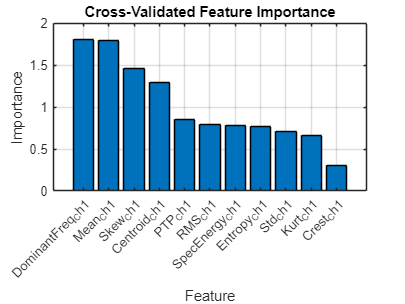


% Plot Feature Importance Bar
figure;
bar(rfM.featureImp);
title('Cross-Validated Feature Importance');
xlabel('Feature');
ylabel('Importance');
xticks(1:length(rfM.featureNames));
xticklabels(rfM.featureNames);
xtickangle(45);
grid on;


% Top features of each class
for c = 1:numel(rfM.perClassLabels)
    [sortedImp, idx] = sort(rfM.perClassFeatureImp(:,c), 'descend');
    fprintf('Top features for class %s:\n', string(rfM.perClassLabels(c)));
    disp(rfM.perClassFeatureNames(idx(1:5))); % Top 5
end

Top features for class frequency converter №2:


  Columns 1 through 4

    {'DominantFreq_Ch1'}    {'Mean_Ch1'}    {'Skew_Ch1'}    {'Centroid_Ch1'}

  Column 5

    {'PTP_Ch1'}



Top features for class misalignment:


  Columns 1 through 4

    {'Centroid_Ch1'}    {'DominantFreq_Ch1'}    {'Skew_Ch1'}    {'Mean_Ch1'}

  Column 5

    {'Entropy_Ch1'}



Top features for class serviceable bearing:


  Columns 1 through 4

    {'Skew_Ch1'}    {'Mean_Ch1'}    {'DominantFreq_Ch1'}    {'PTP_Ch1'}

  Column 5

    {'Centroid_Ch1'}



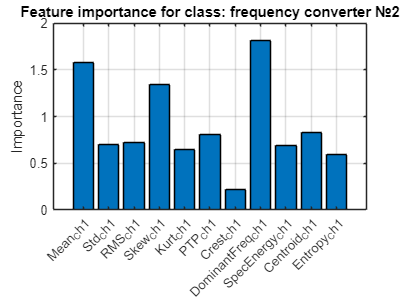

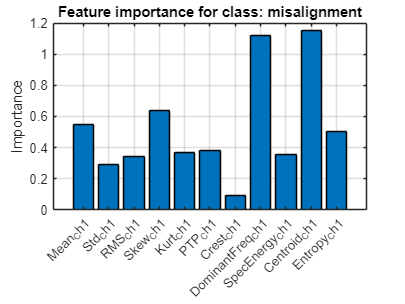

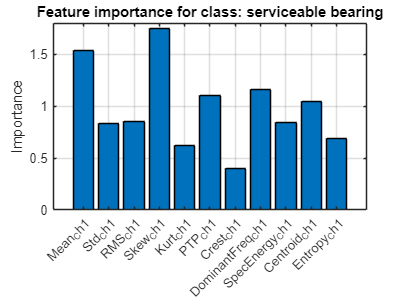


% Per-class imp
for classIdx = 1:length(rfM.perClassLabels) % For the first class
    figure;
    bar(rfM.perClassFeatureImp(:, classIdx));
    set(gca, 'XTick', 1:numel(rfM.perClassFeatureNames), 'XTickLabel', rfM.perClassFeatureNames, 'XTickLabelRotation', 45);
    title(sprintf('Feature importance for class: %s', string(rfM.perClassLabels(classIdx))));
    ylabel('Importance');
    grid on;
end

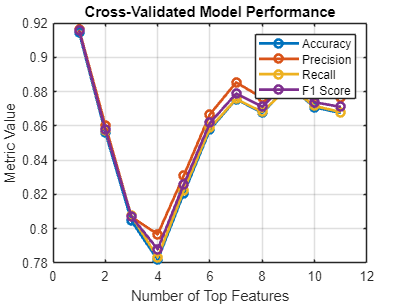


% Plot Metrics vs. Number of Features
figure;
plot(rfM.metrics, '-o', 'LineWidth', 2);
legend('Accuracy', 'Precision', 'Recall', 'F1 Score');
xlabel('Number of Top Features');
ylabel('Metric Value');
title('Cross-Validated Model Performance');
grid on;


% Print Best Metrics + Features
metricNames = ["Accuracy", "Precision", "Recall", "F1 Score"];

for loopIdx = 1:4
    [loopBestVal, loopBestIdx] = max(rfM.metrics(:, loopIdx));
    fprintf('Best %s: %.4f with %d features\n', metricNames(loopIdx), loopBestVal, loopBestIdx);
    disp(rfM.featureNames(1:loopBestIdx)');
end

Best Accuracy: 0.9144 with 1 features


    {'DominantFreq_Ch1'}



Best Precision: 0.9161 with 1 features


    {'DominantFreq_Ch1'}



Best Recall: 0.9154 with 1 features


    {'DominantFreq_Ch1'}



Best F1 Score: 0.9156 with 1 features


    {'DominantFreq_Ch1'}

